### 初始化

clc;
clear

### 参数设置

M = 100000;
Fs = 10E6;
% pathname = 'Data\Instrument_Capture_2023_761k_2.csv';
pathname = 'C:\Users\Labuser\Desktop\InstrumentStudio\Data\Instrument_Capture_06_Multiplier (7) Oscilloscope - Waveform Data.csv';
% pathname = 'Noise.csv';

### 数据读取

range_index_head = ['A' num2str(11)];
range_index_tail = ['B' num2str(10+M)];
range_index = [range_index_head ':' range_index_tail];
wave_data = readmatrix(pathname,"Range",range_index);
vout = wave_data(:,1) - wave_data(:,2);

### 计算THD

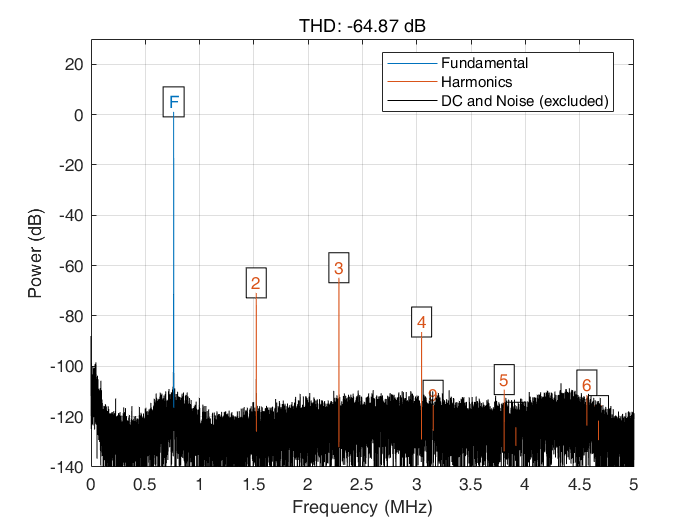

ans = -64.8671

figure
thd(vout, Fs, 9, 'aliased')

### Output results

[r, harmpow, harmfreq] = thd(vout, Fs, 9, 'aliased');
channel = 1

channel = 1

Time = datetime('now', 'InputFormat','dd-MMM-uuuu HH:mm:ss');
THD = r;
HD = harmpow(1:4);
fid = fopen('results.csv', 'a+')

fid = 3

fprintf(fid, "%s, %s, %d, %d, %d, %.2f, %.2f, %.2f, %.2f, %.2f\n", ...
    Time, pathname, channel,Fs/1E6,M,THD, HD);
fclose(fid);